seatbl = readtable('seatbl.csv');
ipftbl = readtable('ipftbl.csv');
seaOrder = {'RSM','ANN-ReLu','ANN-tanh','ANN-sigmoid'};
seatbl.Var1 = categorical(seatbl.Var1,seaOrder);
ipftbl.Var1 = categorical(ipftbl.Var1,seaOrder);

tiledlayout(1,2)

ax1 = nexttile;
boxplot(seatbl.Var2,seatbl.Var1);

ylim([0 400])
set(gca, 'FontName', 'Times New Roman','FontSize',14)
ylabel(ax1,'SEA Absolute Error')
hold on;
meansea = groupsummary(seatbl.Var2,seatbl.Var1,'mean');
plot(meansea,'-o');
ylim([0 400]);
hold off;

ax2 = nexttile;
boxplot(ipftbl.Var2,ipftbl.Var1);

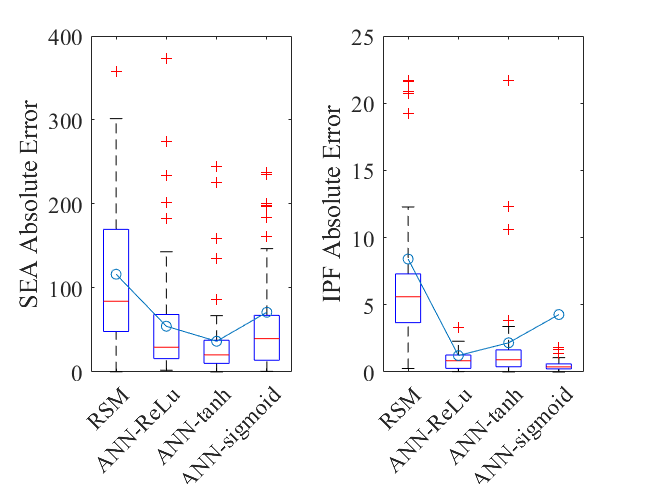

ylim([0 25])
set(gca, 'FontName', 'Times New Roman','FontSize',14)
ylabel(ax2,'IPF Absolute Error')
hold on;
meanipf = groupsummary(ipftbl.Var2,ipftbl.Var1,'mean');
plot(meanipf,'-o');
ylim([0 25]);
hold off;

B = categorical(seaerrcat)

B = 344×1 categorical array
     RSM 
     RSM 
     RSM 
     RSM 
     RSM 
     RSM 
     RSM 
     RSM 
     RSM 
     RSM 
     RSM 
     RSM 
     RSM 
     RSM 
     RSM 
     RSM 
     RSM 
     RSM 
     RSM 
     RSM 
     RSM 
     RSM 
     RSM 
     RSM 
     RSM 
     RSM 
     RSM 
     RSM 
     RSM 
     RSM 


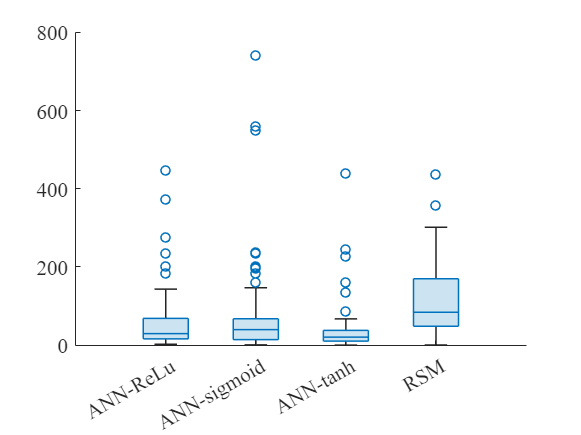

boxchart(B,seaerrval)
set(gca, 'FontName', 'Times New Roman','FontSize',14)

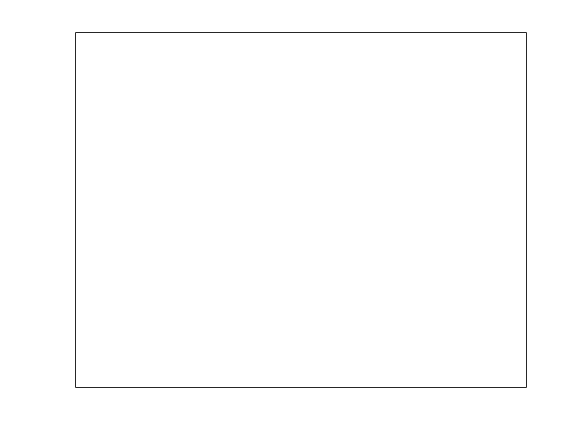

set(gca, 'FontName', 'Times New Roman','FontSize',15)
h=gca; h.XAxis.TickLength = [0 0];
yyaxis right
set( gca, 'YTick', [] )
set( gca, 'YColor', 'k' )
